# **Portada**

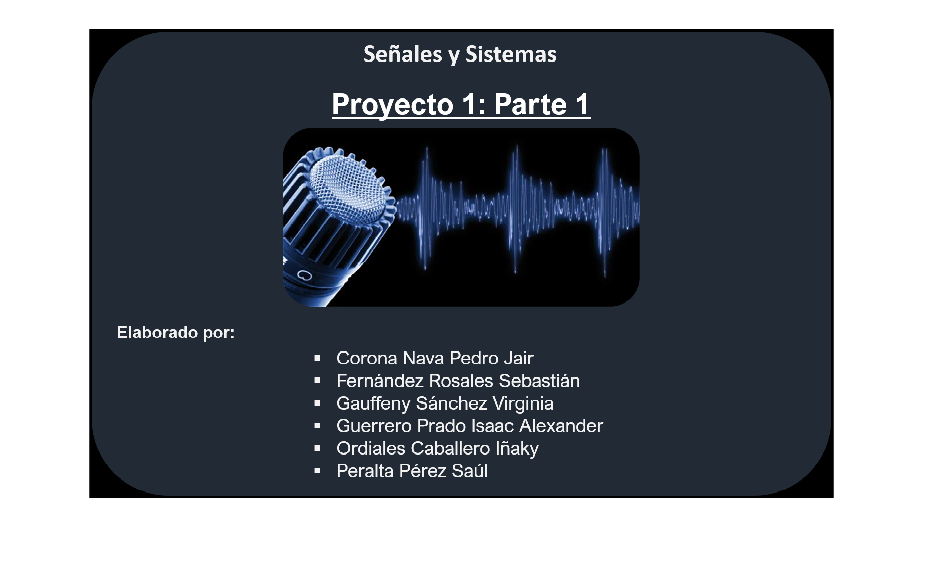

%% NUEVO
clc;
clear;
imshow("PortadaP1.png");

# **Obtencion del audio**

fprintf(" Cómo desea ingresar su audio?\n");

 Cómo desea ingresar su audio?


fprintf("\t1. Seleccionar archivo en la carpeta actual.\n");

	1. Seleccionar archivo en la carpeta actual.


fprintf("\t2. Grabar un audio nuevo.\n\n");

	2. Grabar un audio nuevo.



prompt = ' Opción audio: ';
opcion = input(prompt);

while(opcion~=1 && opcion~=2)
    fprintf(" \n ** La opción no es valida, vuelva a ingresar un valor.\n");
    opcion = input(prompt);
end

if(opcion==1)
    fprintf("\n Seleccione archivo.\n");
    nombre = uigetfile('*.*');
    [s, fs] = audioread(nombre);
    fprintf(" Archivo seleccionado: '%s'\n", nombre);
    fprintf(" Desea escuchar el audio? (1 para sí, 2 para no).");
    prompt = ' Opción escuchar: ';
    opcion = input(prompt);
    while(opcion~=1 && opcion~=2)
        fprintf(" \n ** La opción no es valida, vuelva a ingresar un valor.\n");
        opcion = input(prompt);
    end
    if(opcion==1)
        fprintf("\n Reproduciendo audio...\n");
        sound(s, fs);
    end
    
else
    recObj = audiorecorder;
    fprintf("\n De cuántos segundos desea la grabación?: ");
    prompt = ' Opción segundos: '
    sec = input(prompt);
    fprintf("\n** Cuando este listo, apriete una tecla para empezar a grabar.\n");
    pause();
    fprintf("\n Comience a hablar.\n");
    fprintf(" -------------------\n");
    fprintf("\n GRABANDO \n");
    recordblocking(recObj, sec);
    fprintf(" -------------------\n");
    fprintf(" La grabación terminó.\n");
    s = getaudiodata(recObj);
    fs = 8000;
    fprintf(" Desea guardar el audio en un archivo? (1 para sí, 2 para no): ");
    prompt = ' Opción guardar: ';
    opcion = input(prompt);
    while(opcion~=1 && opcion~=2)
        fprintf(" \n ** La opción no es valida, vuelva a ingresar un valor.\n");
        opcion = input(prompt);
    end
    if(opcion==1)
        prompt = ' Ingrese el nombre del archivo, sin extensión: ';
        nombre = input(prompt,'s');
        nombre = strcat(nombre, '.wav');
        audiowrite(nombre, s, fs);
        fprintf("\n Audio guardado...\n");
    end
end


 Seleccione archivo.


 Archivo seleccionado: 'AudioPrueba.mp4'


 Desea escuchar el audio? (1 para sí, 2 para no).


fprintf("\n Oprima una tecla para continuar ...\n");


 Oprima una tecla para continuar ...


pause();
%% [s fs] = audioread('Nombre del audio'); %% Se quita porque se maneja antes


# **Acondicionamiento**

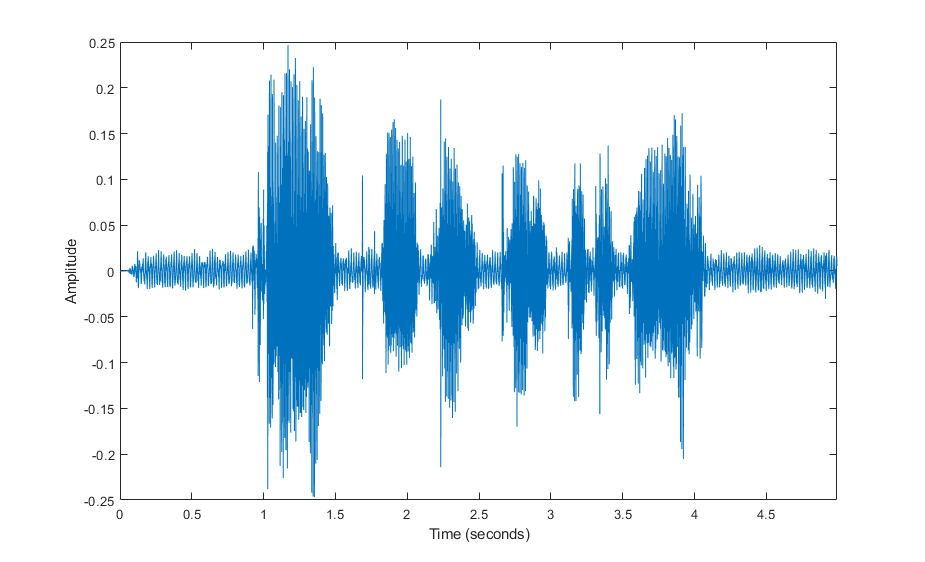

modi=s(:,1);
t=(0:1/fs:(length(modi)-1)/fs);
plot(t,modi)
xlabel('Time (seconds)')
ylabel('Amplitude')
xlim([0 t(end)])

n = length(modi); 
Npower2= 2^nextpow2(n);

# **FFT**

y = fft(modi,Npower2)/n;  
f = (0:length(y)-1)*fs/length(y);
power =  2*abs(real(y(1:Npower2/2+1)));  

# **Espectro de frecuencia**

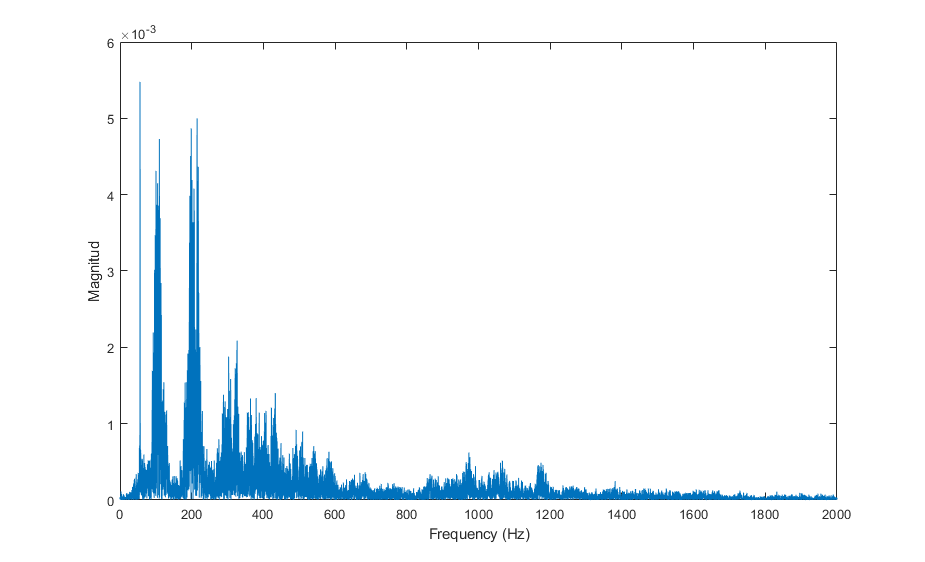

plot(f(1:(Npower2/2)),power(1:(Npower2/2)))
xlabel('Frequency (Hz)'), xlim([0 2000])
ylabel('Magnitud')

# **Identificación Armónico Principal**

[pks, frecs] = findpeaks(power(1:floor(Npower2/2)), f(1:floor(Npower2/2)));
[pks, sortIdx] = sort(pks, 'descend');

pks2 = pks(1:150)';

frecs = frecs(sortIdx);
frecs = round(frecs(1:150));
[frecs2, Idx] = uniquetol(frecs,0.03,"OutputAllIndices",true);

inicio = length(Idx);
contador = inicio;
frecuenciasPico = zeros(inicio,1);

while(contador>0)
    contador = contador-1;
    frecuenciasPico(inicio-contador) = mean(frecs(Idx{inicio-contador}));
end

frecuenciasPico = round(frecuenciasPico')

frecuenciasPico =     56    96   109   120   130   185   197   211   221   294   306   324   364   380   407   429


fprintf(" Frecuencia del pico mayor: %d Hz\n", frecs(1));

 Frecuencia del pico mayor: 56 Hz


fprintf(" Magnitud del pico mayor: %f\n\n", pks(1));

 Magnitud del pico mayor: 0.005478



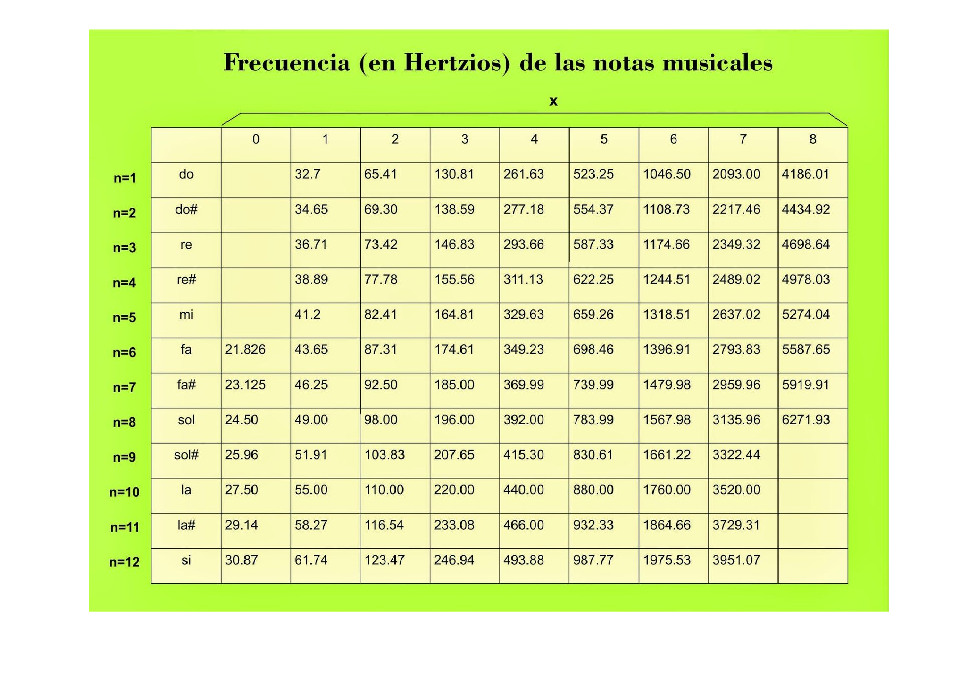

imshow('Frecs.jpg')